# Experimental Fluids Lab #3

**Import and Initialize Pressure Vectors**

% C:\Users\dlawson6\Desktop\Raw Lab Data\Experimental Methods Lab#3\Pressures
% Simply double click the file listed above

% Pressure data sampled at 800 Hz

% Wind off is from 0ms to ~187.5ms, or time = [1, 151]

% Steady State run time is from 400ms to 900 ms, or time = [321, 721]

% Time vector runs from 0 -> 2.5 sec over 2000 points

% Create Steady state pressure vectors

Pitot_SS = Pitot(321:721, 1);
Static3_SS = Static3(321:721, 1);
Static4_SS = Static4(321:721, 1);

Bias = 2; % Pressure transducer bias of +2 mBar
% Bias_pitot = mean(Pitot(1:151, 1)); % Pitot probe bias taken from wind-off (mBar)
% Bias_stat3 = mean(Static3(1:151, 1)); % Static port #3 bias taken from wind-off (mBar)
% Bias_stat4 = mean(Static4(1:151, 1)); % Static port #4 bias taken from wind-off (mBar)

P_o2 = (mean(Pitot_SS + Bias)) / 1000 % Pitot Probe mean pressure over steady state run time (Bar)

P_o2 = 1.8532

P_stat3 = (mean(Static3_SS + Bias) ) / 1000; % Static port #3 mean pressure over steady state run time (Bar)
P_stat4 = (mean(Static4_SS + Bias) )/ 1000; % Static port #4 mean pressure over steady state run time (Bar)
P_stat = (P_stat3 + P_stat4) / 2 % Averaged Static Pressure (Bar)

P_stat = 0.3115


P_ratio_vec = (Pitot_SS ) ./ (((Static3_SS ) + (Static4_SS )) / 2); % Pressure ratio Vector


**Plot Pressure Ratio vs Time**

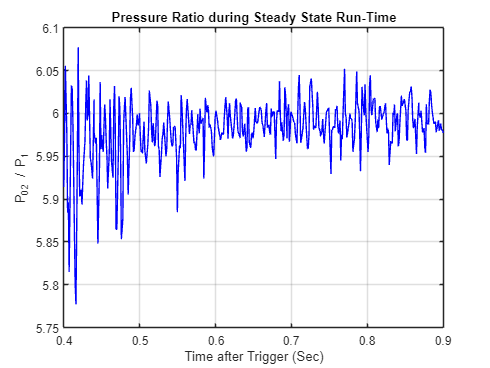

figure
plot(time(321:721),P_ratio_vec,'b')
hold on

title('Pressure Ratio during Steady State Run-Time')
xlabel ('Time after Trigger (Sec)')
ylabel ('P_02 / P_1')
grid on
xlim([0.4 0.9]);

hold off

**Find Mean and STD Via Correlation Analysis**

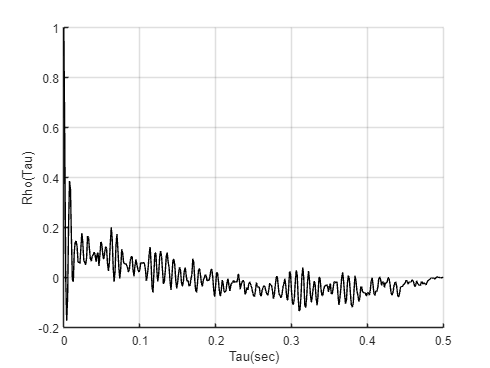

% Use code from class slides

P_fsamp = 800;
[rho,lags] = xcorr(P_ratio_vec - mean(P_ratio_vec),'coeff');

figure
hold on

plot(lags/P_fsamp, rho, '-k');
grid on
xlim([0 0.5])
ylabel('Rho(Tau)')
xlabel('Tau(sec)')

hold off

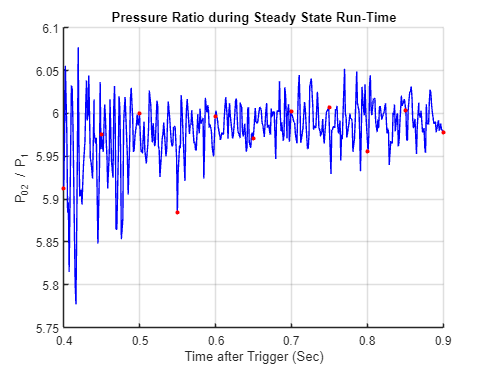


tcorr = 0.05; % Estimated Tcorr value taken from Correlation analysis

D_samp = 1 / tcorr; % Downsample frequency from Tcorr value

samp_ratio = round(P_fsamp / D_samp); % Ratio of sampling rates

P_down = downsample(P_ratio_vec, samp_ratio); % downsampled Pressure Ratio

T_down = linspace(0.4, 0.9,length(P_down));

% Replot Pressure Trace with Downsampled Pressure
figure
hold on

plot(time(321:721),P_ratio_vec,'b')
plot(T_down,P_down,'r.', MarkerSize=10)
title('Pressure Ratio during Steady State Run-Time')
xlabel ('Time after Trigger (Sec)')
ylabel ('P_02 / P_1')
grid on
xlim([0.4 0.9]);

hold off


corr_std = std(P_down)

corr_std = 0.0400

corr_error = t_value(0.9, 10) * (corr_std / sqrt(11)); % Nu = N - 1, where N is our sample count
P_ratio_vec_mean = mean(P_ratio_vec);

fprintf('Correlated Mean = %.3f +/- %.3f', P_ratio_vec_mean, corr_error) 

Correlated Mean = 5.982 +/- 0.022

**Determine Incoming Flow Mach Number**

% Use the Rayleigh Pitot formula simplified for gamma = 1.4

P_o2_stat = P_o2 / P_stat % Mean pressure ratio value

P_o2_stat = 5.9500


% (P_o2 / P1) = (6*M^2 / 5)^3.5 * (6 / (7*M^2 - 1))^2.5

% Define the range of M
M = 0.7:0.005:3;

% Calculate y (P_o2 / P1) for each possible value of M
y = (6*M.^2 / 5).^3.5 .* (6 ./ (7*M.^2 - 1)).^2.5;

% Plot the equation
figure
hold on

plot(M, y, 'b-');
xlabel('M1');
ylabel('P0_2 / P_Static');
title('Mach Numbers Vs Pressure Ratios');
grid on;

M1 = M(273) % M(xxx) where xxx is the array index that matches closest to the calculated (P0_2 / P_Static)

M1 = 2.0600

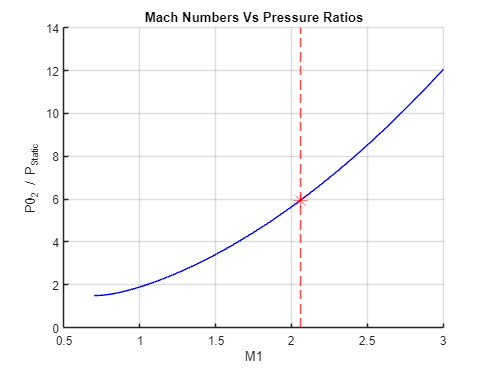


plot(M1, y(273), 'r*', 'MarkerSize', 12)
xline(M1, 'r--')
% yline(P_o2_stat,'r--')

hold off